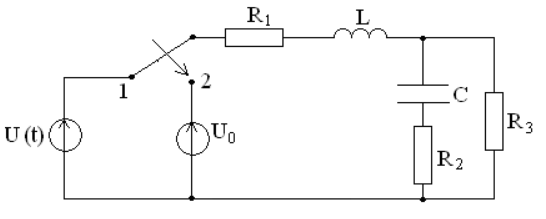

label = {'В';'Гц';'В';'Ом';'Ом';'Ом';'Гн';'Ф'};
val = [99+99*i;1500;50;40;35;250;30e-3;6e-6];
T = table(label,val,...
    'VariableNames',{'unit','value'},...
    'RowNames',{'U','fi','U_0','R_1','R_2','R_3','L_1','C_2'}...
    )

T = 8×2 table
           unit      value  
           ____    _________

    U      'В'        99+99i
    fi     'Гц'     1500+0i 
    U_0    'В'        50+0i 
    R_1    'Ом'       40+0i 
    R_2    'Ом'       35+0i 
    R_3    'Ом'      250+0i 
    L_1    'Гн'     0.03+0i 
    C_2    'Ф'     6e-06+0i 


Вычисления при положении рубильника в позиции 1

omeg = 2*pi*T{'fi','value'}  %расчет угловой скорости

omeg = 9.4248e+03

X_R_1 = T{'R_1','value'};   %расчет реактивного сопротивлнения элементов
X_R_2 = T{'R_2','value'};
X_R_3 = T{'R_3','value'};
X_L = omeg * T{'L_1','value'} *i;
X_C = 1/(omeg*T{'C_2','value'}*i);

Z_2 = X_C+X_R_2;  %расчет суммарного сопротивления на ветвях
Z_3 = X_R_3;
Z_23 = (1/Z_2 + 1/Z_3)^-1;
Z = Z_23+X_R_1+X_L;
I = T{'U','value'}/Z;%расчет тока на главной ветви
I_2 = I*(Z_3/(Z_3+Z_2));     %расчет тока на 2 ветви
I_3 = I*(Z_2/(Z_2+Z_3));     %расчет тока на 3 ветви
U_R_1 = I*X_R_1;%расчет напряжений на каждом элементе
U_R_2 = I_2*X_R_2;
U_R_3 = I_3*X_R_3;
U_L = I*X_L;
U_C = I_2*X_C

U_C = -3.4805 - 6.9607i

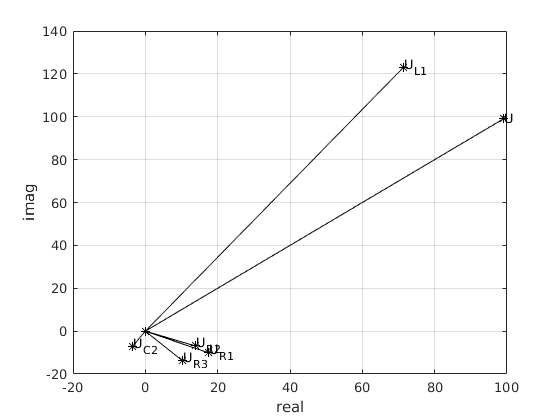

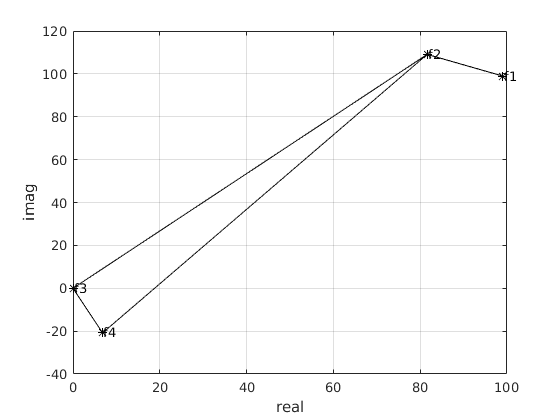

%построение графиков
imag2plot({T{'U','value'} U_R_1 U_R_2 U_R_3 U_L U_C},{'U' 'U_R_1' 'U_R_2' 'U_R_3' 'U_L_1' 'U_C_2'})

f4 = 0;  %расчет потенциалов
f3 = f4+U_R_3;
f4 = f3+U_C;
f2 = f3+U_L;
f1 = f2+U_R_1;
f3 = f1-T{'U','value'};
imag2plot_2({{f3 f4 f2 f1} {f3 f2}},{{'f3' 'f4' 'f2' 'f1'} {'f3' 'f2'}})

Расчет принужденной составляющей при положении рубильника в позиции 2

Ток на конденсаторе и напряжение на катушке будут равны нулю.

I_L_pr = (T{'R_1','value'}+T{'R_3','value'})^-1*T{'U_0','value'}

I_L_pr = 0.1724

U_C_pr = T{'U_0','value'}-(T{'R_1','value'}*I_L_pr)

U_C_pr = 43.1034

Составление характеристического уравнения, нахождение постоянных интегрирования.

В формуле комплексного входного споротивления мы заменяем $j\omega$ на $p$

R_1 = T{'R_1','value'};
R_2 = T{'R_2','value'};
R_3 = T{'R_3','value'};
C_2 = T{'C_2','value'};
L_1 = T{'L_1','value'};
syms p;
Z_ = ((R_2+1/(C_2*p))*R_3/(R_2+R_3+1/(C_2*p)))+R_1+L_1*p;

Получем квадратное уравнение. Рассчитываем:

simplify(Z_)

$$ans = \frac{1514108753570080035\,p^{2}+4453781889156434232568\,p+8559289250201231949824000}{100\,\left(504702917856693345\,p+295147905179352825856\right)}$$

p = round(solve(Z_))

$$p = \left(\begin{array}{c} -1471-1868\,\mathrm{i}\\ -1471+1868\,\mathrm{i} \end{array}\right)$$

Так как у нас получились комплексные значения, то общее характеристическое уравнение:${i_{\mathrm{св}} =\mathrm{Ae}}^{-\alpha t} *\mathrm{sin}\left(\omega_0 t+\psi \right)$

syms A psi
func1 = A*sin(psi)==0.298

$$func1 = A\,\sin\left(\psi \right)=\frac{149}{500}$$

func2 = 1868*A*cos(psi)-1471*A*sin(psi)==-1376

$$func2 = 1868\,A\,\cos\left(\psi \right)-1471\,A\,\sin\left(\psi \right)=-1376$$

format short
sol = solve(func1,func2)

sol = struct with fields:
      A: [2×1 sym]
    psi: [2×1 sym]


sol.A

$$ans = \left(\begin{array}{c} -\frac{\sqrt{297261832265}}{934000}\\ \frac{\sqrt{297261832265}}{934000} \end{array}\right)$$

sol.psi

$$ans = \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sqrt{297261832265}}{278332}-\frac{468821}{278332}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{297261832265}}{278332}+\frac{468821}{278332}\right) \end{array}\right)$$

func3 = @(t) 0.583.*exp(-1471.*t).*sin(1868.*t+2.61)

func3 = function_handle with value:
    @(t)0.583.*exp(-1471.*t).*sin(1868.*t+2.61)


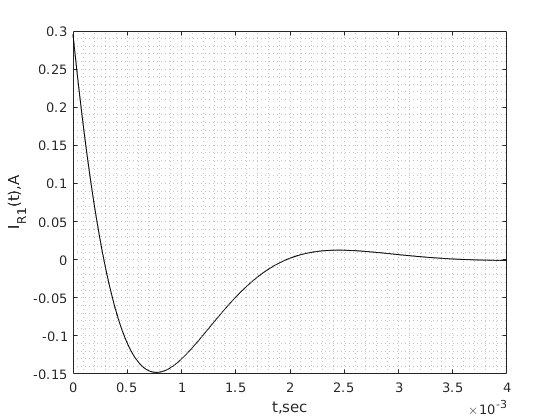

plot(0:1e-6:4e-3,func3(0:1e-6:4e-3),'k-')
grid minor
xlabel('t,sec')
ylabel('I_R_1(t),A')

Где А и $\psi_0$ - коэффециенты характеристического уравнения.

syms p
func1 = p^2+p*6111.1+16.67*10^6;
round(solve(func1))

$$ans = \left(\begin{array}{c} -3056-2708\,\mathrm{i}\\ -3056+2708\,\mathrm{i} \end{array}\right)$$

ans = 0.8325

function imag2plot(arr, leg)
hold off
for n = 1:length(arr)
    rvar = real(arr{n});
    ivar = imag(arr{n});
    plot([0 rvar],[0 ivar], 'k-*')
    hold on
end
for m = 1:length(leg)
    text(real(arr{m})+.2,imag(arr{m})+.2,leg{m});
    hold on
end
%legend('boxoff');
grid on
xlabel('real')
ylabel('imag')
hold off
end
function imag2plot_2(arr, leg)
hold off
for n = 1:length(arr)
    for m = 2:length(arr{n})
        rvar_1 = real(arr{n}{m-1});
        ivar_1 = imag(arr{n}{m-1});
        rvar_2 = real(arr{n}{m});
        ivar_2 = imag(arr{n}{m});
        plot([rvar_1 rvar_2],[ivar_1 ivar_2], 'k-*')
        hold on
    end
end
for n = 1:length(leg)
    for m = 1:length(leg{n})
        if n==1
            text(real(arr{n}{m})+.2,imag(arr{n}{m})+.2,leg{n}{m});
            hold on
        elseif m~=1 && m~=length(leg{n})
            text(real(arr{n}{m})+.2,imag(arr{n}{m})+.2,leg{n}{m});
            hold on
        end
    end
end
%legend('boxoff');
grid on
xlabel('real')
ylabel('imag')
hold off
end